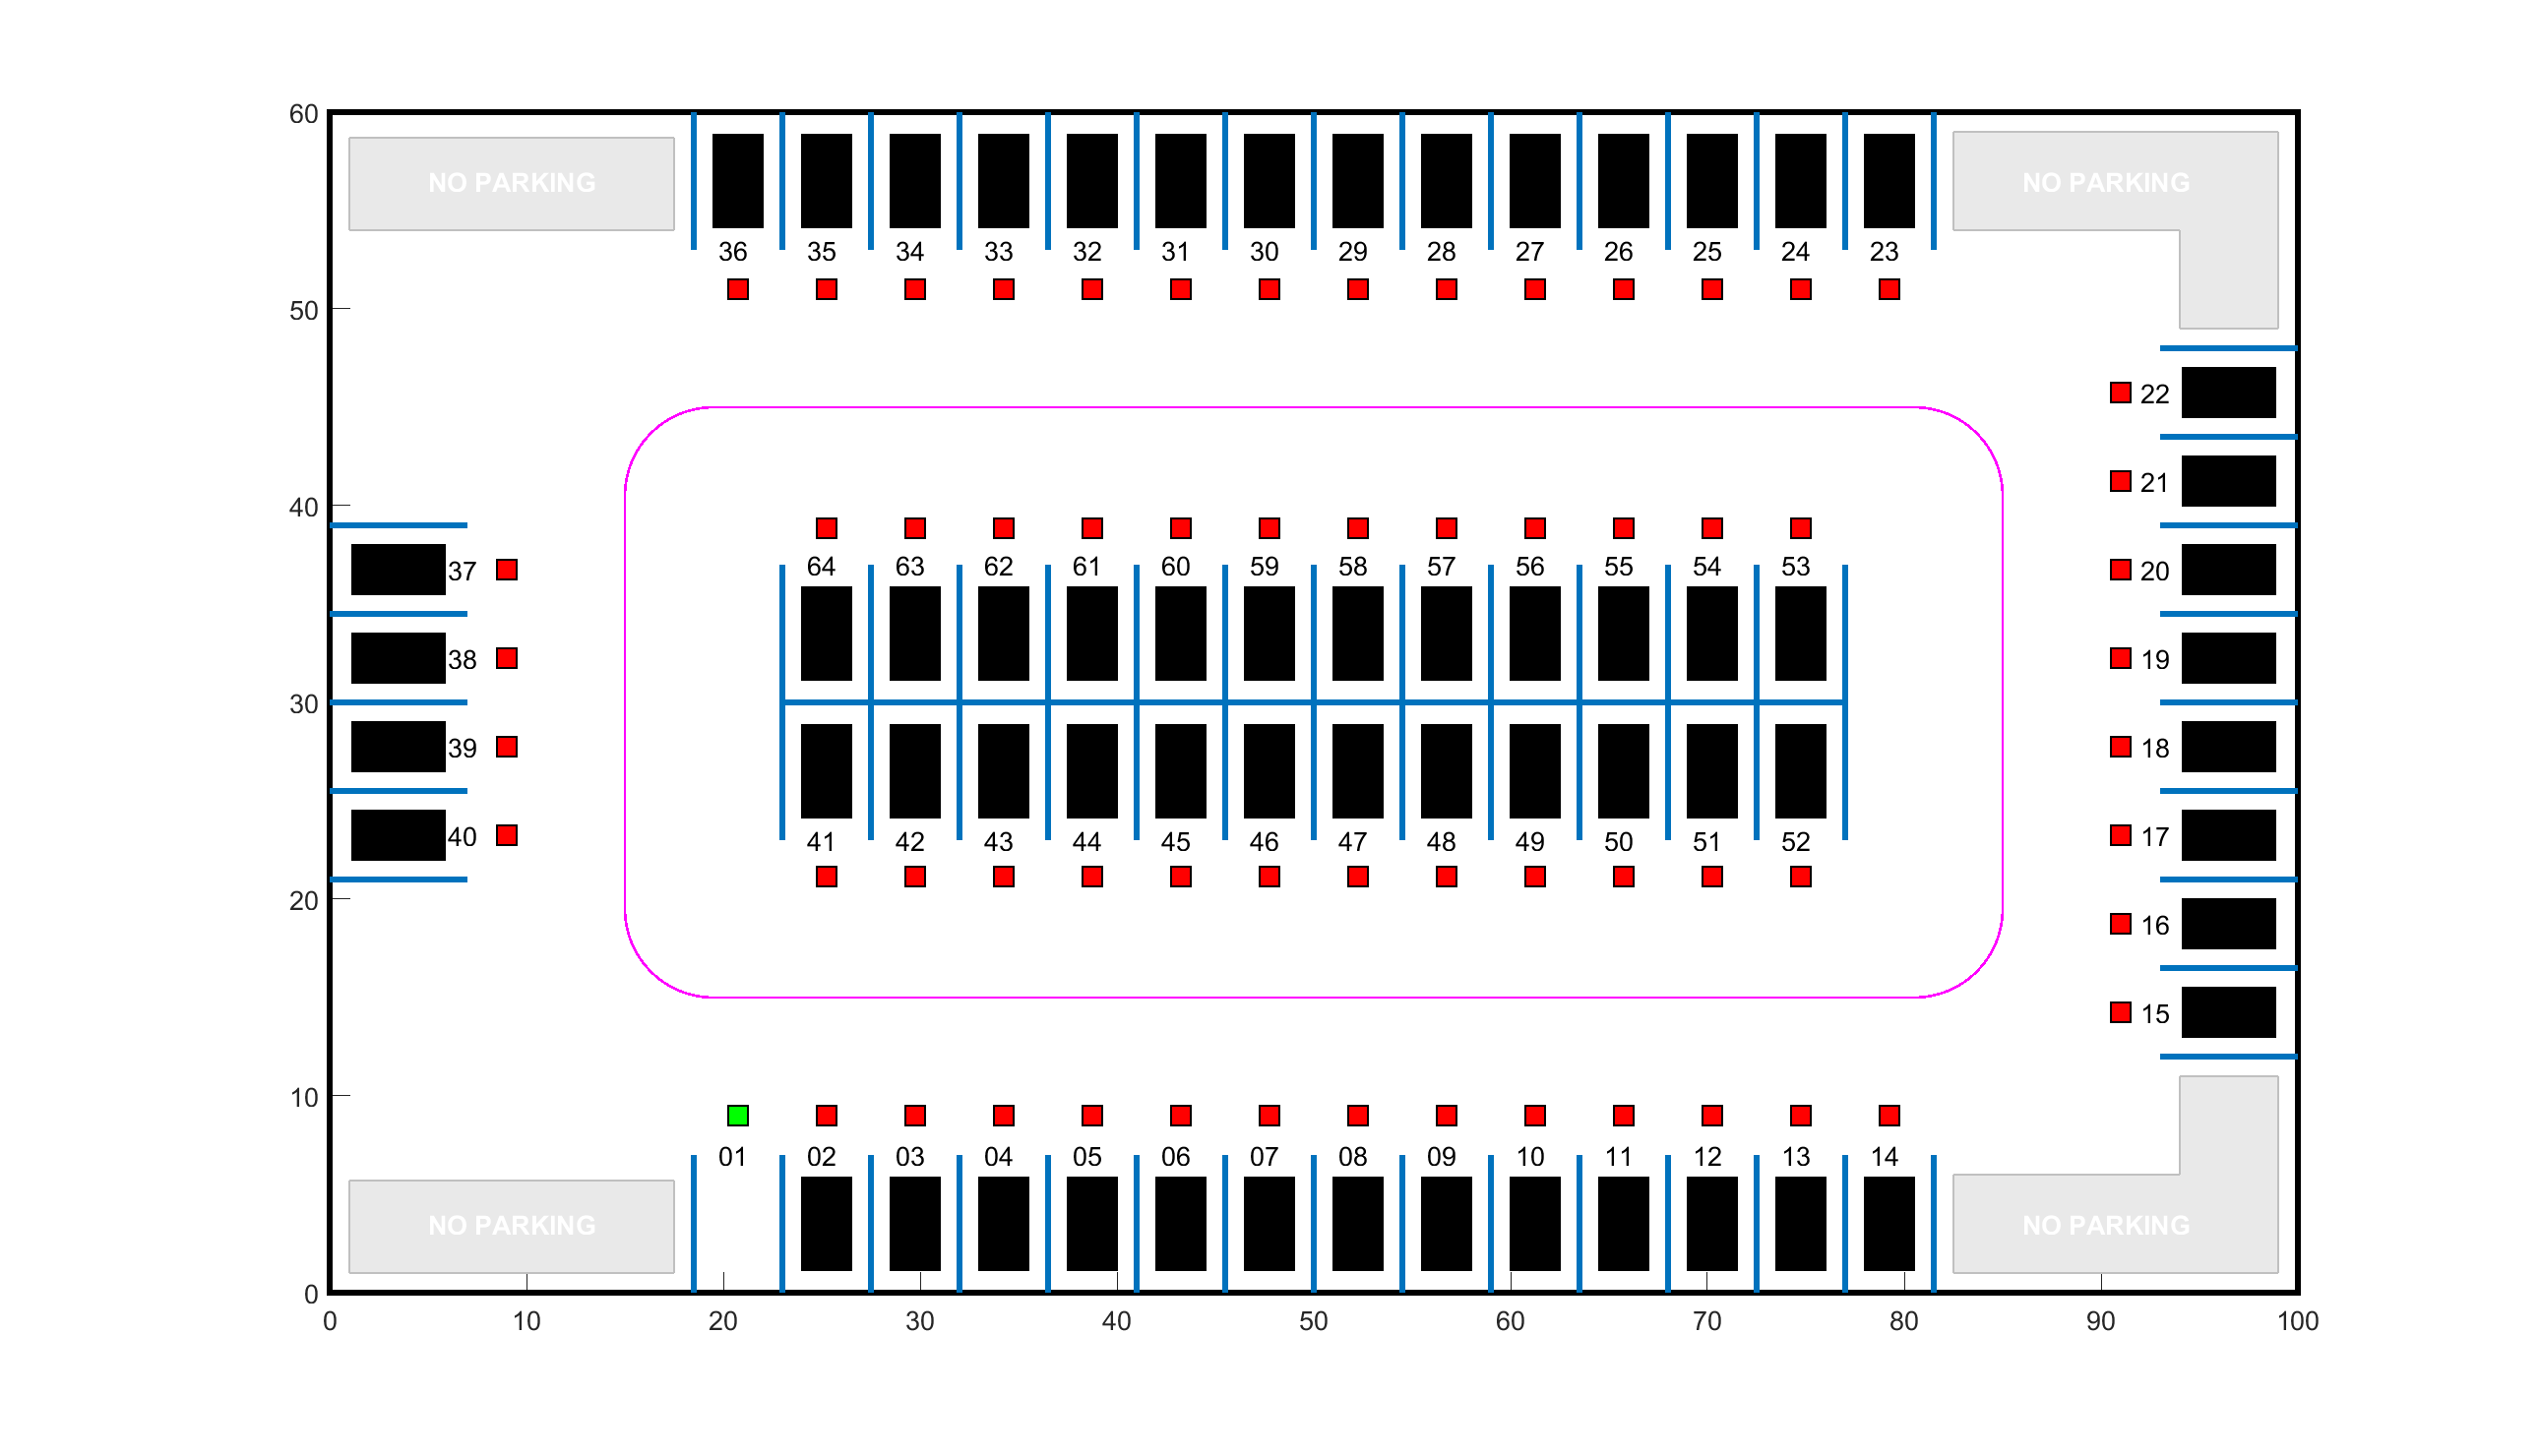

freeSpotIdx = 1;
map = ParkingLot(freeSpotIdx);


egoInitialPose = [20, 15, 0];
egoTargetPose = createTargetPose(map,freeSpotIdx)

egoTargetPose =    20.7500    4.9000   -1.5708


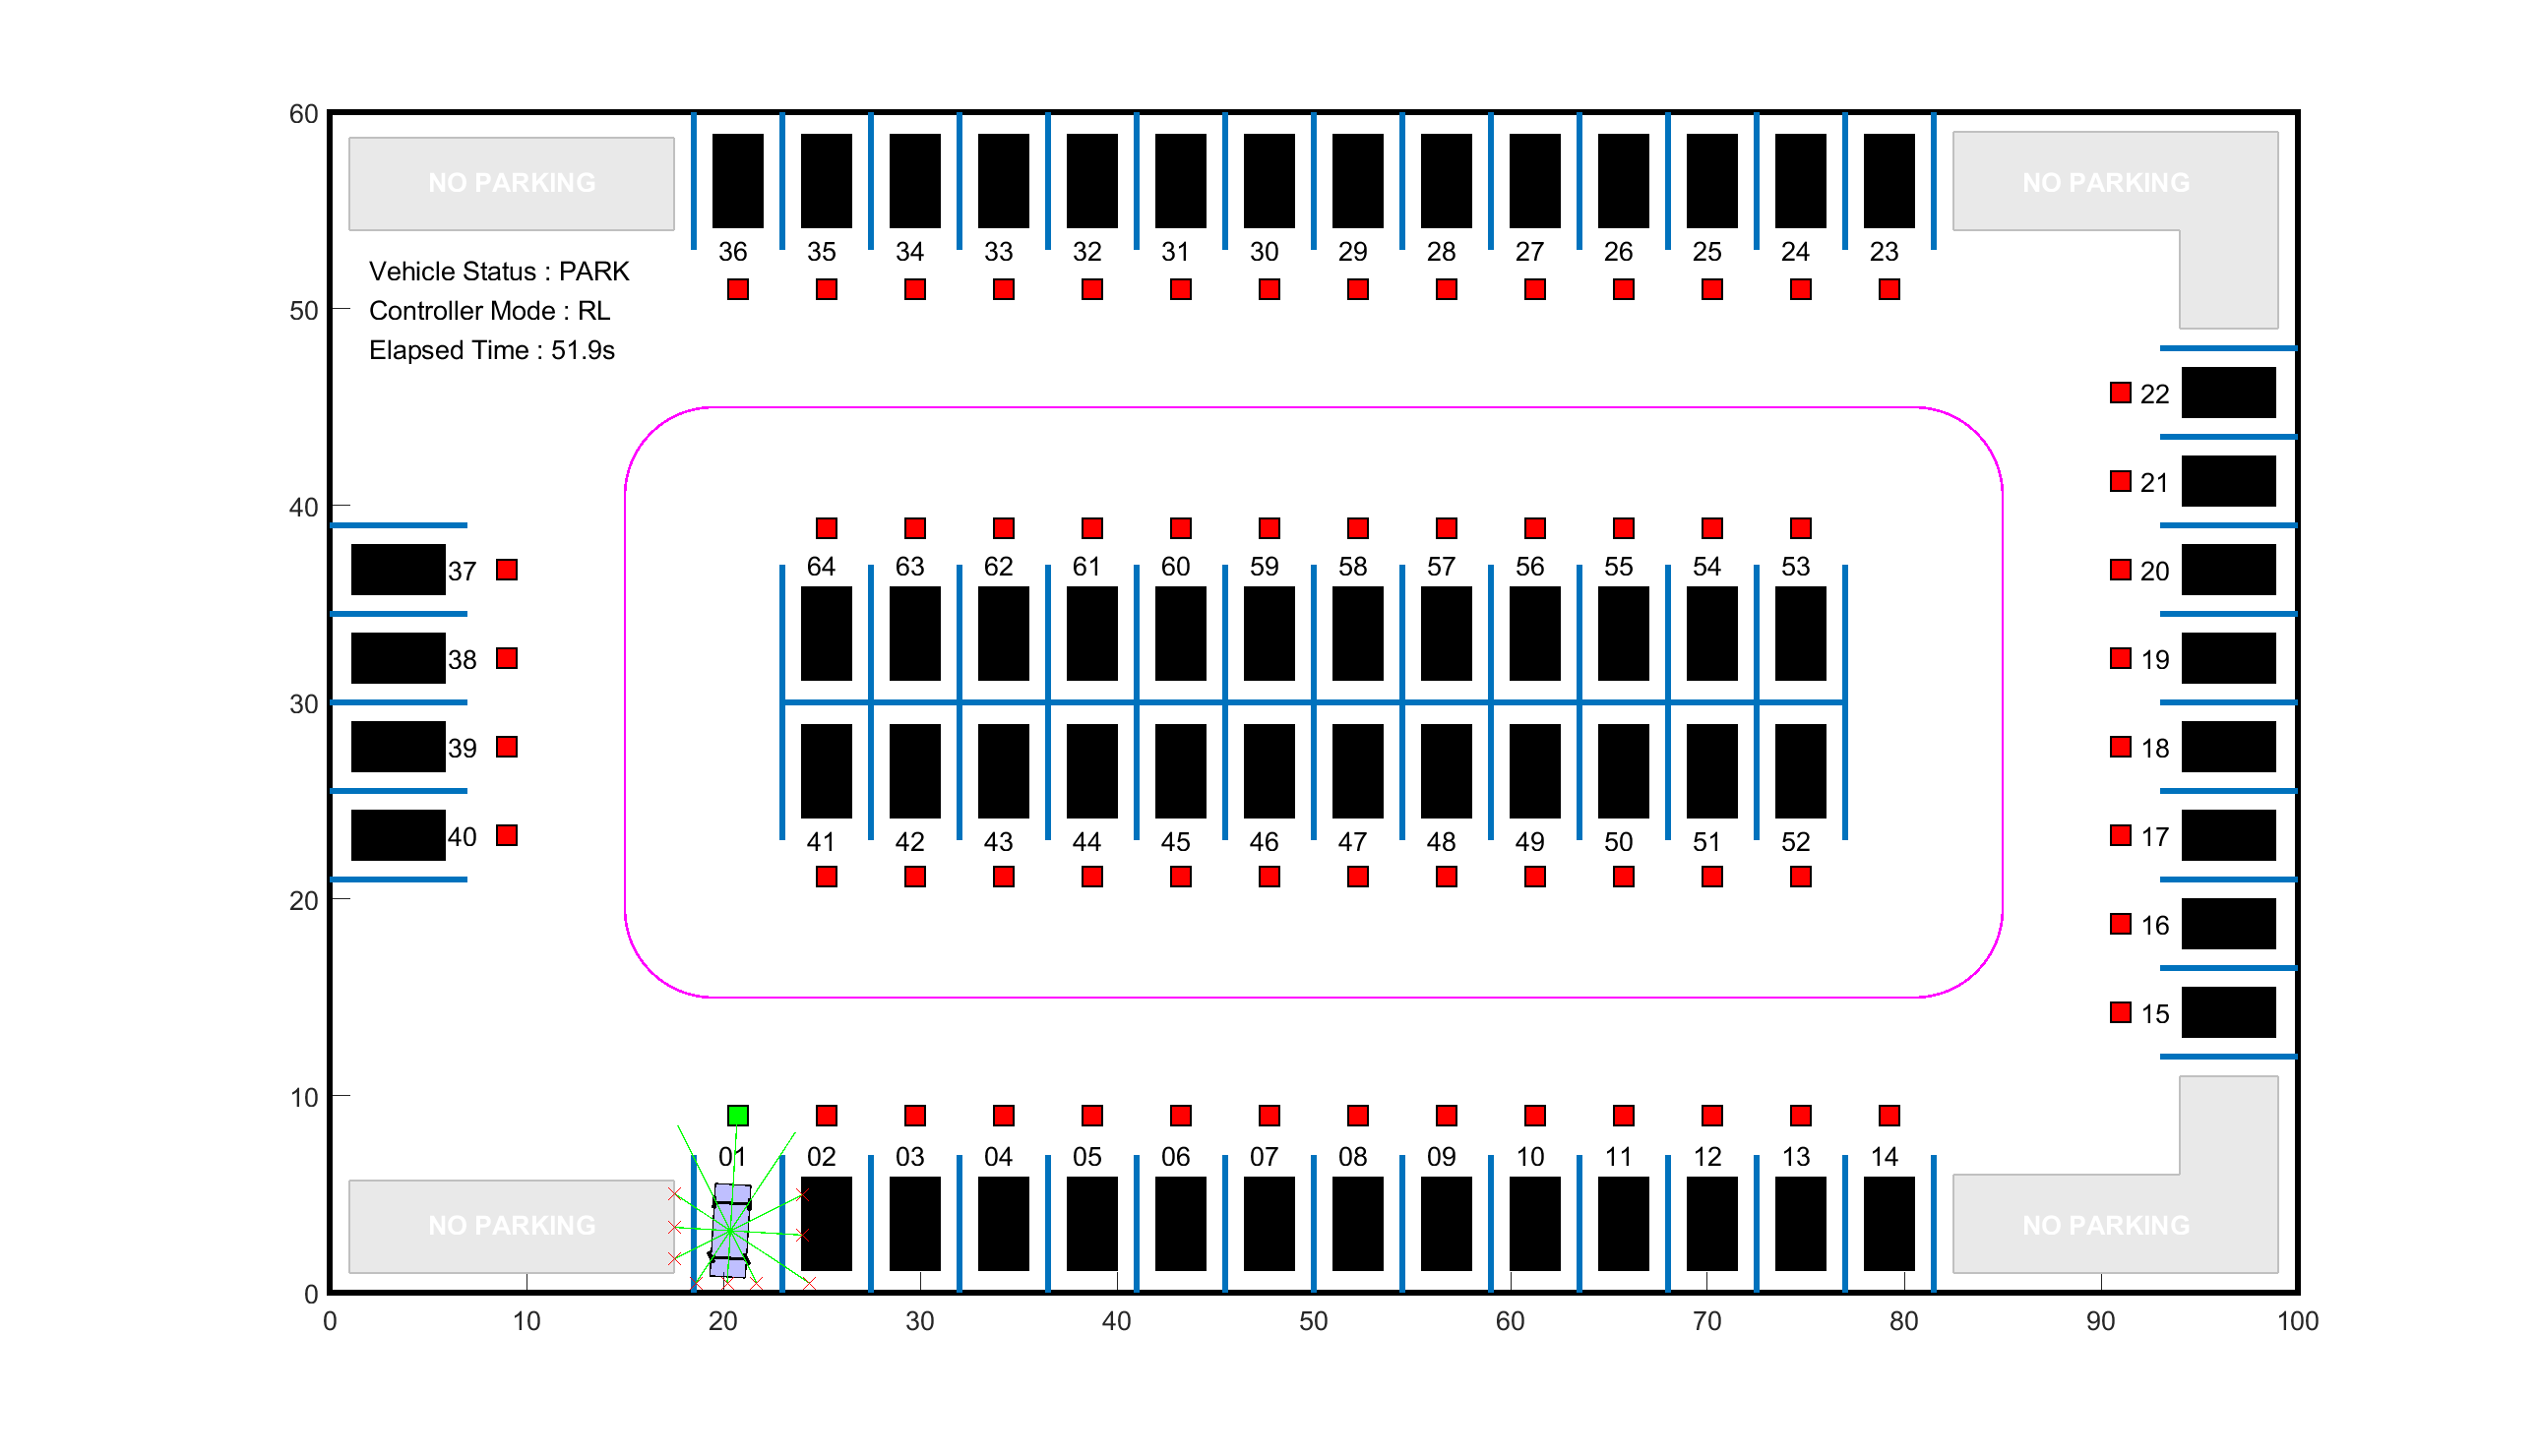

ans =   Simulink.SimulationOutput:

                   tout: [547x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 



autoParkingValetParams
mdl = "rlAutoParkingValet";
open_system(mdl)

createMPCForParking

numObservations = 16;
obsInfo = rlNumericSpec([numObservations 1]);
obsInfo.Name = "observations";

numActions = 1;
actInfo = rlNumericSpec([numActions 1], 'LowerLimit', -1, 'UpperLimit', 1);
actInfo.Name = "actions";

blk = mdl + "/RL Controller/RL Agent";
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);

env.ResetFcn = @autoParkingValetResetFcn;

rng(0)

criticNet = [
    featureInputLayer(numObservations)
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(1)
    ];

criticNet = dlnetwork(criticNet);
%analyzeNetwork(criticNet);

critic = rlValueFunction(criticNet,obsInfo);

%% === Actor Network ===
% Common feature extractor
actorBase = [
    featureInputLayer(numObservations, Name="input")
    fullyConnectedLayer(128)
    reluLayer(Name="relu1")
    fullyConnectedLayer(128)
    reluLayer(Name="relu2")
];

% Mean output
meanPath = [
    fullyConnectedLayer(numActions, Name="meanFC")
    tanhLayer(Name="meanLayer")
];

% Std output
stdPath = [
    fullyConnectedLayer(numActions, Name="stdFC")
    softplusLayer(Name="stdLayer")
];

actorLG = layerGraph(actorBase);
actorLG = addLayers(actorLG, meanPath);
actorLG = addLayers(actorLG, stdPath);
actorLG = connectLayers(actorLG, "relu2", "meanFC");
actorLG = connectLayers(actorLG, "relu2", "stdFC");

actorNet = dlnetwork(actorLG);
%analyzeNetwork(actorNet);

actor = rlContinuousGaussianActor(actorNet, obsInfo, actInfo, ...
    ActionMeanOutputNames="meanLayer", ...
    ActionStandardDeviationOutputNames="stdLayer", ...
    ObservationInputNames="input");

criticOptions = rlOptimizerOptions( ...
    LearnRate=1e-3, ...
    GradientThreshold=1);
actorOptions = rlOptimizerOptions( ...
    LearnRate=2e-4, ...
    GradientThreshold=1);

agentOpts = rlPPOAgentOptions(...
    SampleTime=Ts,...
    ActorOptimizerOptions=actorOptions,...
    CriticOptimizerOptions=criticOptions,...
    ExperienceHorizon=200,...
    ClipFactor=0.2,... 
    EntropyLossWeight=0.01,...
    MiniBatchSize=64,...
    NumEpoch=3,...
    AdvantageEstimateMethod="gae",...
    GAEFactor=0.94,...
    DiscountFactor=0.998);

agent = rlPPOAgent(actor,critic,agentOpts);

trainOpts = rlTrainingOptions(...
    MaxEpisodes=10000,...
    MaxStepsPerEpisode=200,...
    ScoreAveragingWindowLength=200,...
    Plots="training-progress",...
    StopTrainingCriteria="EpisodeCount",...
    StopTrainingValue=2000);

doTraining = false;
if doTraining
    trainingStats = train(agent,env,trainOpts);
    save("TrainingResult.mat","agent")
else
    load('rlAutoParkingValetAgent.mat','agent');
end

sim(mdl)

open_system(mdl + "/Ego Vehicle Model/Ego Vehicle Pose")

% Simpan hasil training: Episode, Episode Reward, Average Reward, dan Q0
numEpisodes = numel(trainingStats.EpisodeIndex);  % Ambil jumlah episode

Unable to resolve the name 'trainingStats.EpisodeIndex'.

episodeReward = trainingStats.EpisodeReward;      % Episode reward
averageReward = trainingStats.AverageReward;      % Average reward
episodeQ0 = trainingStats.EpisodeQ0;              % Q0 di setiap episode
step1 = trainingStats.EpisodeSteps;
step2 = trainingStats.TotalAgentSteps;

% Buat tabel untuk menyimpan data
rewardTable = table((1:numEpisodes)', episodeReward(:), averageReward(:), episodeQ0(:), step1(:), step2(:),...
                    'VariableNames', {'Episode', 'EpisodeReward', 'AverageReward', 'EpisodeQ0', 'EpisodeSteps', 'TotalAgentSteps'});

% Simpan ke file Excel
writetable(rewardTable, 'TrainingResultsPPOOriginal.xlsx');

% Tampilkan tabel di Command Window
disp('Reward Table:');
disp(rewardTable);